clear; close all; clc;

# EE 514 Term Project

**Authors: **M. Gallagher; B. Kwan

**Description: **The following file will define the variables used within the Simulink model `motomatic_pend.slx` which models a nonlinear pendulum attached to the Motomatic.

## Defining Physical Parameters and Sensor Gains

The following lines of code will define the sensor gains and physical parameters used for the simulation.

Ka     = 5.1793;     % Power Amplifier
N      = 8.1;        % Speed Reduction Factor
Km     = 22.289;     % Motor gain [rad/s/V]
Km_lin = 19.763;     % Linearized motor gain [rad/s/V]
tau_m  = .2740;      % Motor time constant [s]
Kp     = 4.90379;    % Position Feedback Gain
Kt     = .1429;
vmo    = 0.66;       % Voltage to hold pendulum at 90 degrees [V]
g      = 9.81;       % gravitational acceleration [m/s/s]

#### Defining physical parameters of the pendulum

L = 11;      % Pendulum rod length [in]
L = L/39.37; % Pendulum rod length [m]
m = 28/1000; % Bob mass [kg]
physParam = [m, L, g, vmo, N];

The next line will define the intial condition of the pendulum

th_init = deg2rad(110);

## Stability Analysis

The Jacobian of the system without the input was found to be:


$$J=\left\lbrack \begin{array}{cc}
0 & 1\\
\textrm{MgL}*\frac{\cos \left(0\right)}{\;\left({N\;J}_m +J_p \right)} & -N\;\frac{J_m }{\tau_m \left({N\;J}_m +J_p \right)}
\end{array}\right\rbrack$$


% Based on the physical parameters of the model, find the polar moments of
% inertia of the motor and pendulum
J_p = m*L^2;                    % Polar moment inertia of pendulum [kg*m^2]
J_m = m*g*L/vmo*(tau_m/Km_lin); % Polar moment inertia of motor [kg*m^2]
J = [0 1;
    m*g*L*cos(0)/(N*J_m+J_p), -N*J_m/tau_m/(N*J_m+J_p)];
eig(J);

## Linear Quadratic Optimal Control

The following section will focus on finding the optimal gain for the linearized system

A = J;    % The A matrix is simply the Jacobian of the system evaluated the equilibrium point
B = [0 m*g*L/(vmo*(N*J_m+J_p))]';
%Q = 2*eye(2);    % State cost matrix
%R = 2;    % Input cost matrix

%set values with no state cost
Q = [1000, 0; 0, 0];
R = 1;


% implement the CARE
syms p11 p12 p22
P = [p11 p12; p12 p22];
%CAREout = A'*P + P*A - P*B*inv(R)*B'*P + Q == 0;
CAREout = A'*P + P*A - P*B*inv(R)*B'*P + Q == 0;
struct = solve(CAREout(1,1),CAREout(1,2),CAREout(2,1),CAREout(2,2));
p11_sol = double(struct.p11);
p12_sol = double(struct.p12);
p22_sol = double(struct.p22);

for i = 1:length(struct.p11)
    K = inv(R)*B'*[p11_sol(i) p12_sol(i); p12_sol(i) p22_sol(i)];
    eigstar = double(eig(A-B*K));
    if eigstar(1) < 0 && eigstar(2) < 0
        Kstar = K
    end
end

Kstar =    32.2897    2.5285


%[Kstar, S, eigstar] = lqr(A, B, Q, R, [0]);

## Running the Simulation

The following line of code runs the simulation for a user-defined amount of time.

simout = sim('motomatic_pend.slx',2);

## Data Analysis

The following section will focus on plotting the data with the LQR implemented.

#### Phase trajectory plot

By plotting the states of the system against each other, one can study the behavior of the system.

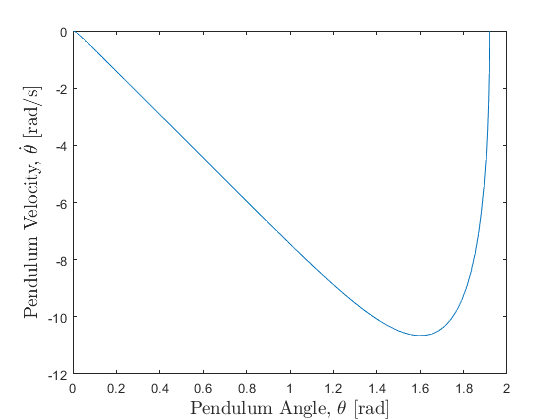

phasetrajec = figure;
plot(simout.X(:,1),simout.X(:,2))
xlabel('Pendulum Angle, $\theta$ [rad]','Interpreter','Latex','FontSize',14); 
ylabel('Pendulum Velocity, $\dot{\theta}$ [rad/s]','Interpreter','Latex','FontSize',14);

#### Control Effort Plot

Plotting the control effort of the system can give an insight as to how the system is stabilizing itself. 

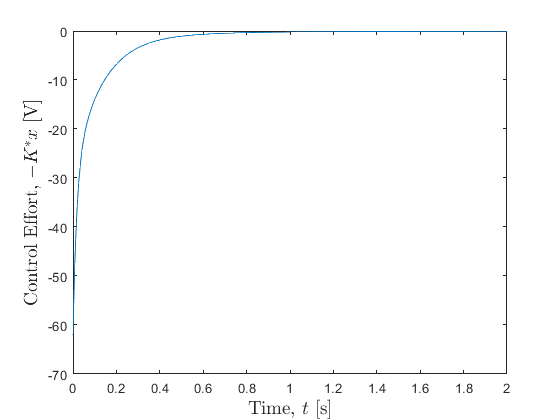

control_eff = figure;
plot(simout.tout,simout.ctrl_eff)
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Control Effort, $-K^*x$ [V]','Interpreter','Latex','FontSize',14);

cost = figure;
costval = zeros(size(simout.tout,1),1);
intCost = zeros(size(simout.tout,1),1); 
sstime = 0;
for i = 1: size(simout.tout,1)
    %(simout.tout(2) - simout.tout(1))  * simout.X(i,:)*Q*simout.X(i,:)' + simout.ctrl_eff(i) * R * simout.ctrl_eff(i) + sum(costval)
    %costval(i) = (simout.tout(2) - simout.tout(1))  *simout.X(i,:)*Q*simout.X(i,:)' + simout.ctrl_eff(i) * R * simout.ctrl_eff(i);
    if (abs(simout.X(i, 1)) <= 0.05 ) && (abs(simout.X(i, 2)) <= 0.05) && (sstime == 0)
        sstime = simout.tout(i);
    end
    if i > 1
        costval(i) = (simout.tout(i) - simout.tout(i-1))  *simout.X(i,:)*Q*simout.X(i,:)' + simout.ctrl_eff(i) * R * simout.ctrl_eff(i);
        intCost(i) = trapz(simout.tout(1:i), costval(1:i));
    else
        costval(i) = (simout.tout(1))  *simout.X(i,:)*Q*simout.X(i,:)' + simout.ctrl_eff(i) * R * simout.ctrl_eff(i);
        intCost(i) = costval(i) * simout.tout(1:i);
    end
end
sstime

sstime = 0.8247

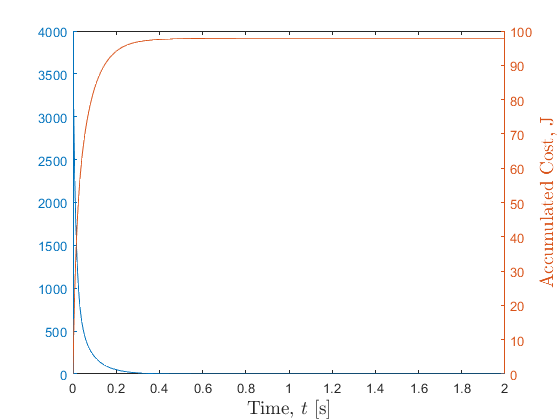

yyaxis left
plot(simout.tout,costval(:))
yyaxis right
ylabel('Instantaneous Cost','Interpreter','Latex','FontSize',14);

%trapz(simout.tout, costval(:,1));
plot(simout.tout,intCost);
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Accumulated Cost, J','Interpreter','Latex','FontSize',14);

## Inverted Pendulum Animation

The following lines of code are unnecessary but interesting to view an animation of the inverted pendulum model

xpend = L*sin(simout.X(:,1));
ypend = L*cos(simout.X(:,1));
fps = 60;
t = 0:1/fps:max(simout.tout);
xpend = interp1(simout.tout,xpend,t);
ypend = interp1(simout.tout,ypend,t);
origin = zeros(1,length(xpend));

The next lines of code create the animation.

pendGif = figure;
pendGif.Visible = 'on';
ax = axes;
axis([-.3 .3 -.2 .4]);xticks([-3:.1:.3])
hold on;
traject = animatedline('color','r','MaximumNumPoints', 15,'LineWidth',2);
arm = plot([origin xpend],[origin ypend],'b-','LineWidth',3);
p = plot(xpend,ypend,'ko', 'MarkerFaceColor','k','MarkerSize',30);
h = fill([-1 1 1 -1],[-1 -1 L*cos(110*pi/180)-.01 L*cos(110*pi/180)-.01],[.5 .5 .5]);
ax = gca;
ax.FontSize = 12;
set(gcf,'position',[0 0 600 600]);
xlabel('Horizontal Position [m]','Interpreter','Latex','FontSize',16);
ylabel('Vertical Position [m]','Interpreter','Latex','FontSize',16);
grid on; box on;
hold off

The following `for` loop is used to refresh the plot for every tick of time defined earlier by the desired fps.

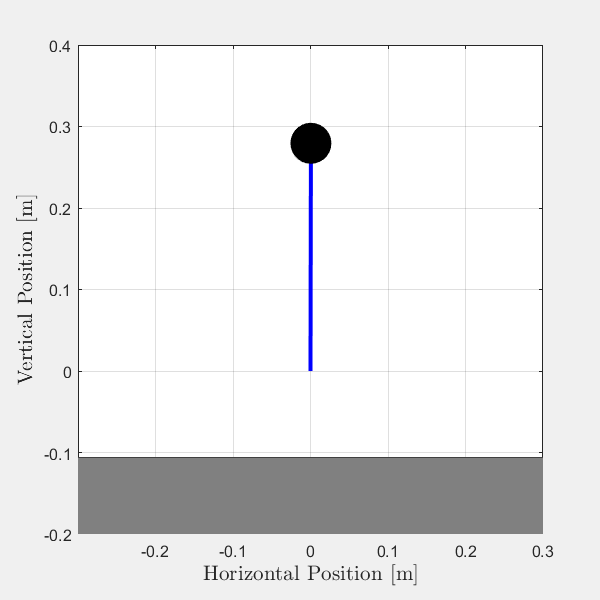

for n = 1:length(t)
    p.XData = xpend(n);
    p.YData = ypend(n);
    arm.XData = [origin(n) xpend(n)];
    arm.YData = [origin(n) ypend(n)];
   
    addpoints(traject,xpend(n),ypend(n));
    drawnow
    
    frame = getframe(pendGif);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    
    if n == 1
        imwrite(imind,cm,'pend.gif','gif','LoopCount', inf,'DelayTime',1/fps);
    elseif n == length(t)
        imwrite(imind,cm,'pend.gif','gif','WriteMode','append','DelayTime',5/fps);
    else
        imwrite(imind,cm,'pend.gif','gif','WriteMode','append','DelayTime',1/fps);
    end
end